# initialization


syms q1 q2 q3 l1 l2 l3 lc1 lc2 lc3 m1 m2 m3 I1 I2 I3 real;


## linear and angular jacobian on the CoG of the link 1



x1 = lc1*cos(q1);
y1 = lc1*sin(q1);
z1 =0;
phi1x=0; phi1y=0 ;phi1z=q1;

Jc1 = [diff(x1,q1),diff(x1,q2),diff(x1,q3);...
          diff(y1,q1),diff(y1,q2),diff(y1,q3);...
          diff(z1,q1),diff(z1,q2),diff(z1,q3)];
 
  Jw1 =[diff(phi1x,q1),diff(phi1x,q2),diff(phi1x,q3);...
      diff(phi1y,q1),diff(phi1y,q2),diff(phi1y,q3);...
      diff(phi1z,q1),diff(phi1z,q2),diff(phi1z,q3)];


## linear and angular jacobian on the CoG of the link 2


  
x2 = l1*cos(q1) + lc2*cos(q1+q2);
y2 = l1*sin(q1) +lc2*sin(q1+q2);
z2 =0;
phi2x=0; phi2y=0 ;phi2z=q1+q2;

Jc2 = [diff(x2,q1),diff(x2,q2),diff(x2,q3);...
          diff(y2,q1),diff(y2,q2),diff(y2,q3);...
          diff(z2,q1),diff(z2,q2),diff(z2,q3)];
 
  Jw2 =[diff(phi2x,q1),diff(phi2x,q2),diff(phi2x,q3);...
      diff(phi2y,q1),diff(phi2y,q2),diff(phi2y,q3);...
      diff(phi2z,q1),diff(phi2z,q2),diff(phi2z,q3)];



## linear and angular jacobian on the CoG of the link 3



x3 = l1*cos(q1) + l2*cos(q1+q2)+ lc3*cos(q1+q2+q3);
y3 = l1*sin(q1) +l2*sin(q1+q2) +lc3*sin(q1+q2+q3);
z3 =0;
phi3x=0; phi3y=0 ;phi3z=q1+q2+q3;

Jc3 = [diff(x3,q1),diff(x3,q2),diff(x3,q3);...
          diff(y3,q1),diff(y3,q2),diff(y3,q3);...
          diff(z3,q1),diff(z3,q2),diff(z3,q3)];
      
  Jw3 =[diff(phi3x,q1),diff(phi3x,q2),diff(phi3x,q3);...
      diff(phi3y,q1),diff(phi3y,q2),diff(phi3y,q3);...
      diff(phi3z,q1),diff(phi3z,q2),diff(phi3z,q3)];


## Inertia matrix


M = m1.*(Jc1'*Jc1) + m2.*(Jc2'*Jc2) +   m3.*(Jc3'*Jc3)   + I1.*(Jw1'*Jw1)  + I2.*(Jw2'*Jw2)+ I3.*(Jw3'*Jw3);

J3 = [Jc3,Jw3];
simplify(J3)'
simplify(M);

m11 = M(1,1); m22=M(2,2);m33=M(3,3);
m12 = M(1,2); m13 =M(1,3); m21=M(2,1);
m23=M(2,3);m31=M(3,1);m32=M(3,2);




## Christoffel coeffient

C =sym('c%d%d',[3,3],'real');
syms qd1 qd2 qd3 real ;

qd =[qd1,qd2,qd3];
q = [q1,q2,q3];
for k=1:1:3
    for j=1:1:3
        C(k,j)=0.0;
        for i=1:1:3
            C(k,j) = C(k,j) + (1/2)*(diff(M(k,j),q(j)) +diff(M(k,i),q(j)) - diff(M(i,j),q(k)))*qd(i);
        end
    end
end

simplify(C);



## potential energy

P =m1*lc1*sin(q1) + m2*(l1*sin(q1)+lc2*sin(q1+q2)) +m3*(l1*sin(q1)+l2*sin(q1+q2)+lc3*sin(q1+q2+q3));

G = [diff(P,q1),diff(P,q2),diff(P,q3)]'




## test FK

q1=pi/5; q2=-pi/7; q3=pi/3;l1=2; l2=2.5; l3=1.5;
x = l1*cos(q1) + l2*cos(q1+q2)+ l3*cos(q1+q2+q3);
y = l1*sin(q1) +l2*sin(q1+q2) +l3*sin(q1+q2+q3);
z =0;
p1 =[x,y,z]';
joints =[q1,q2,q3];
pos = p1 - 1;
pos(3)=0
[theta, td,tdd,err]= IK(joints,pos);

% p2 =FK(theta)
% t=1:1:size(err);
% plot(t,err')


## trajectory of the first robot A =[ -1.6, 2] B=[2.8 , 1.5] Y(t) = x(t)*sin(t*pi/7) both robot

% desired trajectory in the cartesian space for the master
Xm= -1.6:0.1:2.8;

m=size(Xm',1);
t =linspace(0,10,m);
Ym = Xm.*cos(t*pi/7)+3;
% joint space trajectory
Lo =2; % lenght of the object
config=[pi/5,pi/7,-pi/6];
Xf =zeros(m,1);
Yf =zeros(m,1);
joint_space =[]; vel_space =[];acc_space=[];

for  i=1:1:m
   pos=[Xm(i) ,Ym(i),0];
   [theta ,thetad,thetadd ,err] =IK(config,pos');
   config = theta';
   
   Xf(i)=Lo*cos(sum(theta)) +Xm(i );
   Yf(i)=Lo*sin(sum(theta)+ Ym(i));
   
   joint_space=[joint_space theta];
  vel_space =[vel_space thetad];
  acc_space =[acc_space thetadd];
end

## Joint space trajectory of the follower

config1=[pi/5,pi/7,-pi/6];
joint_spacef =[]; vel_spacef =[];acc_spacef=[];

for  i=1:1:m
   pos=[Xf(i) ,Yf(i),0];
   [thetaf ,thetadf,thetaddf ,errf] =IK(config1,pos');
   config1 = thetaf';
   
  joint_spacef=[joint_space theta];
  vel_spacef =[vel_spacef thetadf];
  acc_spacef =[acc_spacef thetaddf];
end


## Object Desired trajectory

Xo =zeros(m,1);
Yo =zeros(m,1);

Xo_dot =zeros(m,1);
Yo_dot  =zeros(m,1);

Xo_ddot =zeros(m,1);
Yo_ddot  =zeros(m,1);
for  i=1:1:m
   Xo(i)=Lo*cos(sum(joint_space(:,i)))/2 +Xm(i );
   Yo(i)=Lo*sin(sum(joint_space(:,i))/2+ Ym(i));
  
end


## torque generated trajectory for the master

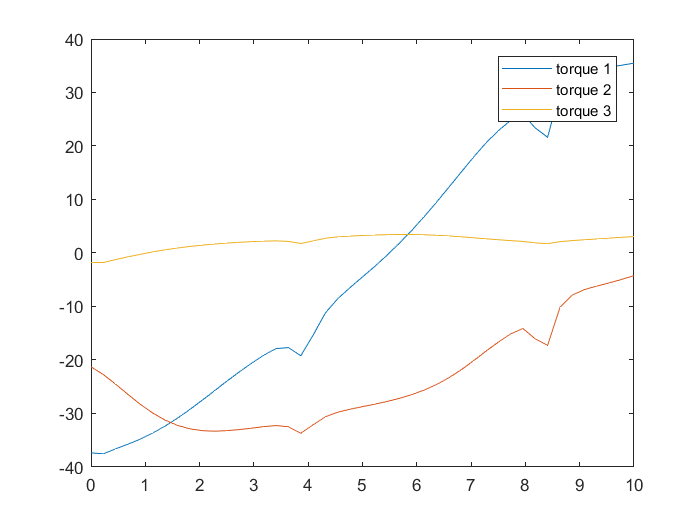


% plot(t,joint_space(1,:))
% legend("Joint 1 Trajectory")
Dt =t(2)-t(1);
% generates torques for each joints
Tau =[];Tau1 =[];
qd_dt =zeros(3,1); qdd_dt=zeros(3,1);
for i=1:1:m
     vel =(joint_space(:,i) - qd_dt)./Dt;
     acc =(vel -qdd_dt)./Dt;
     
     torque1 = inverseDynamic(joint_space(:,i),vel,acc');
     Tau1 =[Tau1 ,torque1];
    
    torque = inverseDynamic(joint_space(:,i),vel_space(:,i),acc_space(:,i)');
    Tau =[Tau ,torque];
    
    qdd_dt =vel;
    qd_dt=joint_space(:,i);
end

  plot(t,Tau(1,:),t,Tau(2,:),t,Tau(3,:)) ;legend("torque 1","torque 2","torque 3");

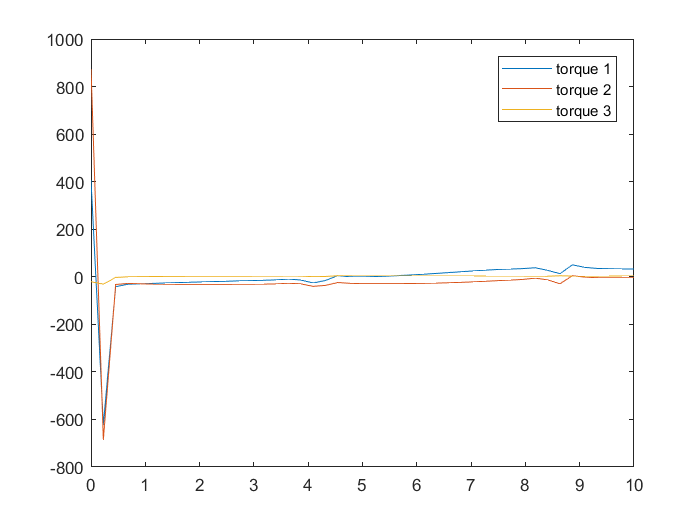

  plot(t,Tau1(1,:),t,Tau1(2,:),t,Tau1(3,:)) ;legend("torque 1","torque 2","torque 3");

## Torque generate trajectory of the follower

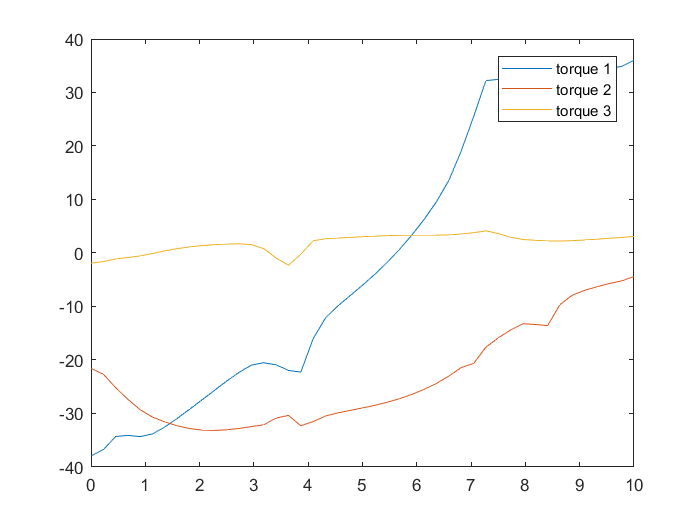


% generates torques for each joints
Tauf =[];Tauf1 =[];
qd_dtf =zeros(3,1); qdd_dtf=zeros(3,1);
for i=1:1:m
     vel =(joint_spacef(:,i) - qd_dtf)./Dt;
     accf =(vel -qdd_dtf)./Dt;
     
     torquef1 = inverseDynamic(joint_spacef(:,i),vel,accf');
     Tauf1 =[Tauf1 ,torquef1];
    
    torquef = inverseDynamic(joint_spacef(:,i),vel_spacef(:,i),acc_spacef(:,i)');
    Tauf =[Tauf ,torquef];
    
    qdd_dtf =vel;
    qd_dtf=joint_spacef(:,i);
end

  plot(t,Tauf(1,:),t,Tauf(2,:),t,Tauf(3,:)) ;legend("torque 1","torque 2","torque 3");

  plot(t,Tauf1(1,:),t,Tauf1(2,:),t,Tauf1(3,:)) ;legend("torque 1","torque 2","torque 3");

## joint trajectory from FD given tau

init = [joint_space(:,1)',0,0,0];
Time =t;
[time ,solve] =ode45(@(t,q)ode3link(t,q,Tau1,Time),t,init);

Error using svd
Input to SVD must not contain NaN or Inf.

Error in pinv (line 18)
[U,S,V] = svd(A,'econ');

Error in ode3link (line 48)
 Qdd = pinv(M)*(F-(C*[qd1,qd2,qd3]'+G));

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('playground>@(t,q)ode3link(t,q,Tau1,Time)')" style="font-weig

 

plot(time,solve(:,1:3)',time,joint_space);
legend("robot 1 q 1","robot1 q2","robot 1 q3","rbot 2 q1","robot 2 q2","robot 2 q3") ;


## Computer torque control

init = [solve(1,1:3),0,0,0];
Kp =eye(3)*10000;
Kd = eye(3)*8000;
T =zeros(3,m);
qc=[0,0,0]'; qdc = [0,0,0]'; qddc =[0,0,0]';
e=[];ed=[];
path = [];
for i=2:m
    qe = solve(i,1:3)' -qc;
    qde = solve(i,4:6)' -qdc;
    u = (solve(i,4:6)' -solve(i-1,4:6)')/Dt + Kd*qe + Kp*qde ;
    tau =inverseDynamic(solve(i,1:3)',solve(i,1:3)',u');
    T(:,i)=tau;
    [time ,sol ] = ode45(@(t,q)ode3link(t,q,T(:,1:i),Time(1:i)),t,init);
    qc= sol(i,1:3)';
    qdc= sol(i,4:6)';
    path = [path qc];
    e=[e,qe]; ed=[ed,qde];
end

Index exceeds matrix dimensions.

## size

size(ed)

ans =      3   408


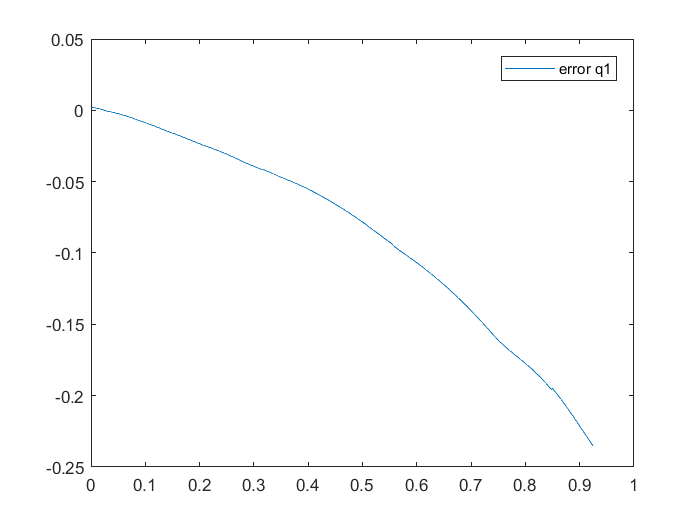

plot(t(1:408),ed(1,1:408)); legend("error q1","error q2","error q3");

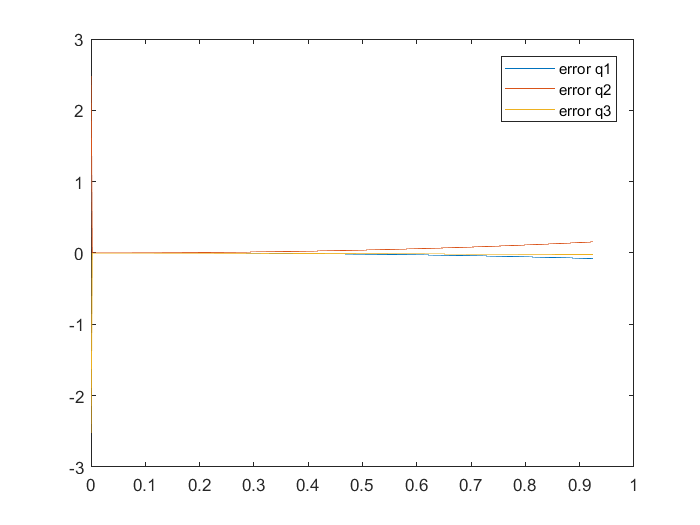

plot(t(1:408),e); legend("error q1","error q2","error q3");

## error in the position

Pd =[];
Pc =[];
for i=1:size(path,2)
  pc =FK(path(:,i));
  pd =FK(solve(i,1:3));
  Pc=[Pc pc];
   Pd=[Pd pd];
end

## plot

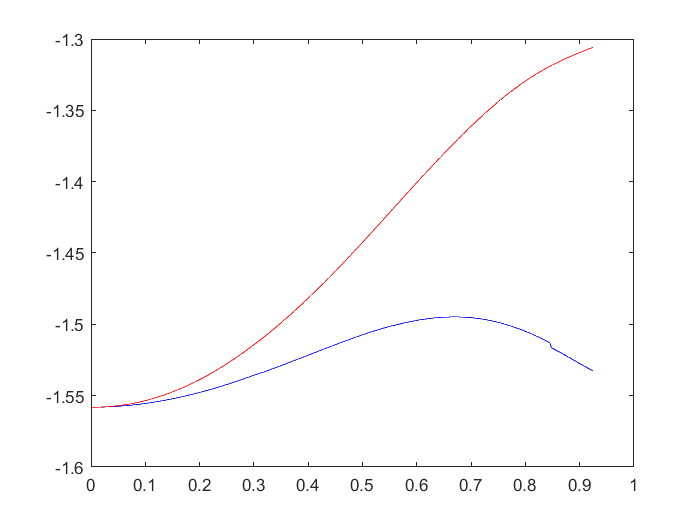


plot(t(1:408),Pc(1,:),'b',t(1:408),Pd(1,:),'r');

## generate a path for the robot

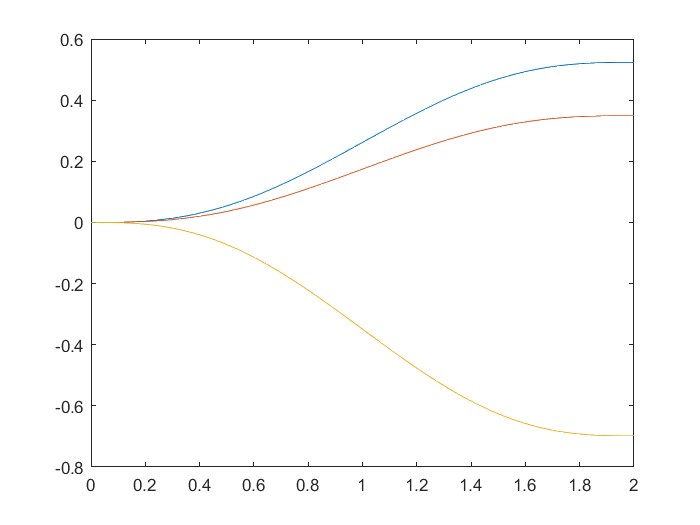

home = [0,0,0]';
dest = [30,20,-40]';
home = deg2rad(home);
dest =deg2rad(dest);
conf= JointPath(home,[0,0,0]',[0,0,0]',dest,[0,0,0]',[0,0,0]',2,100);
time = linspace(0,2,100);
plot(time,conf);

## cartesian path

ee=[]


ee =

     []



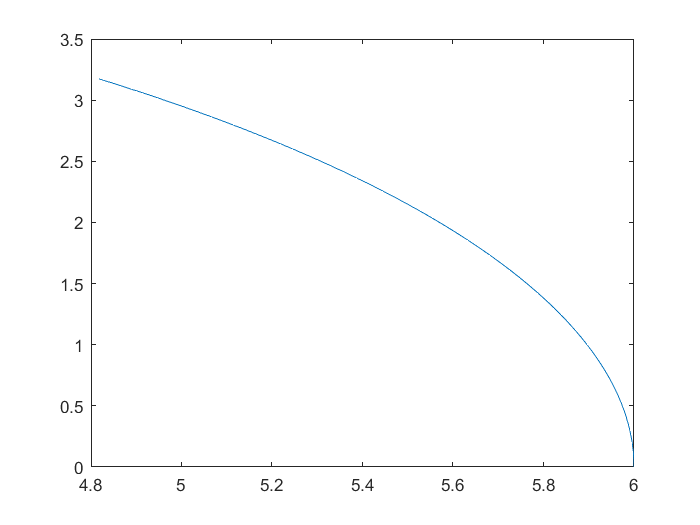

for i=1:size(conf,2)
  pc =FK(conf(:,i));
  
   ee=[ee pc];
end

plot(ee(1,:),ee(2,:))